D = struct with fields:
      D: [128×128×1×27 uint8]
    map: [89×3 double]
    siz: [128 128 27]


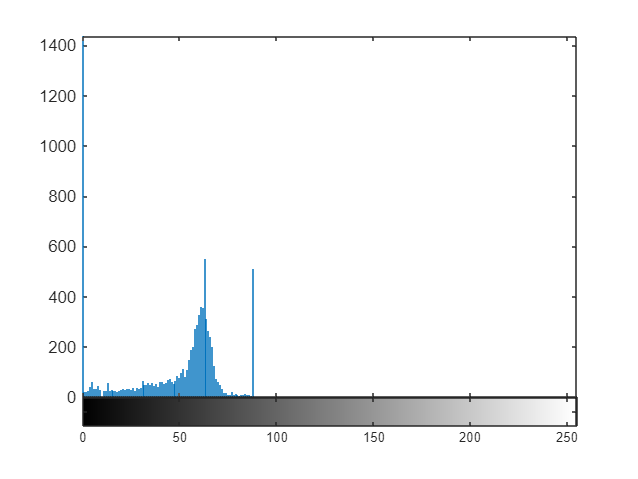

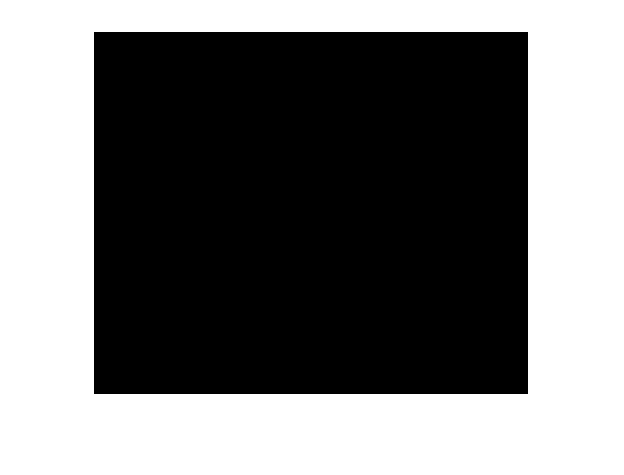

load ("Brain.mat")

%% Create empty masks
mask_11 = zeros(size(T1));
mask_12 = zeros(size(T1));
mask_13 = zeros(size(T1));
mask_14 = zeros(size(T1));
mask_15 = zeros(size(T1));

%% Mask values are assigned with previous 2D segmentaion binaries
mask_11(:,:,9) = final_skin;
mask_12(:,:,9) = final_skull;
mask_13(:,:,9) = final_csfvar;
mask_14(:,:,9) = final_grey_matter;
mask_15(:,:,9) = final_white_matter;

%% Applying 3D active contour to entire image set
bw_11 = activecontour(T1,mask_11,300);
bw_12 = activecontour(T1,mask_12,300);
bw_13 = activecontour(T1,mask_13,300);
bw_14 = activecontour(T1,mask_14,300);
bw_15 = activecontour(T1,mask_15,300);


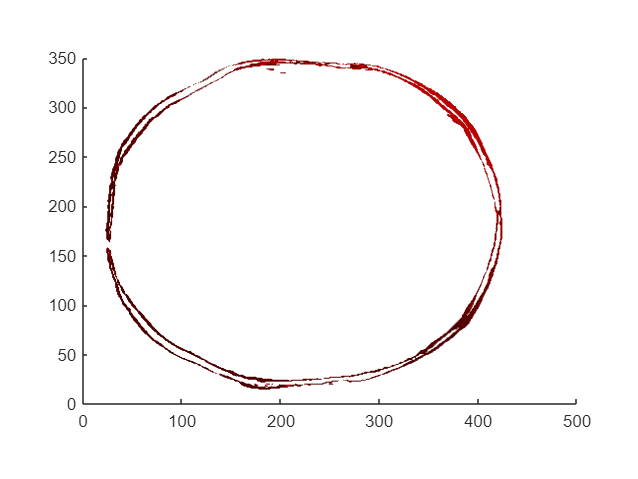

% Display the Skin 3D segment
figure;
p_1 = patch(isosurface(double(bw_11)));
p_1.FaceColor = 'red';
p_1.EdgeColor = 'none';
daspect([1 1 27/128]);
camlight; 
lighting phong

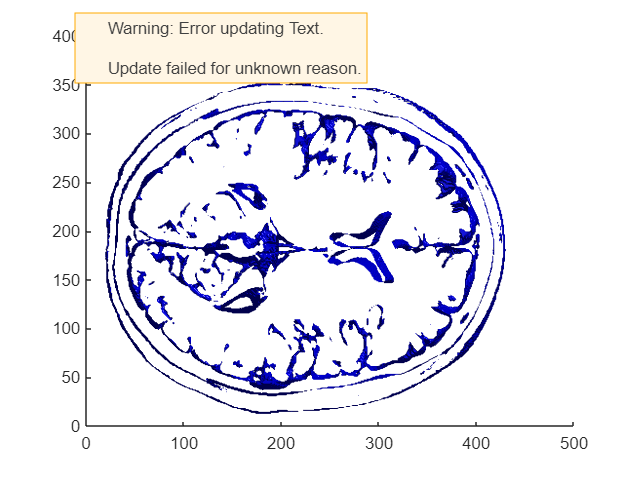

% Display Skull 3D Segment
figure;
p_2 = patch(isosurface(double(bw_12)));
p_2.FaceColor = 'blue';
p_2.EdgeColor = 'none';
daspect([1 1 27/128]);
camlight; 
lighting phong

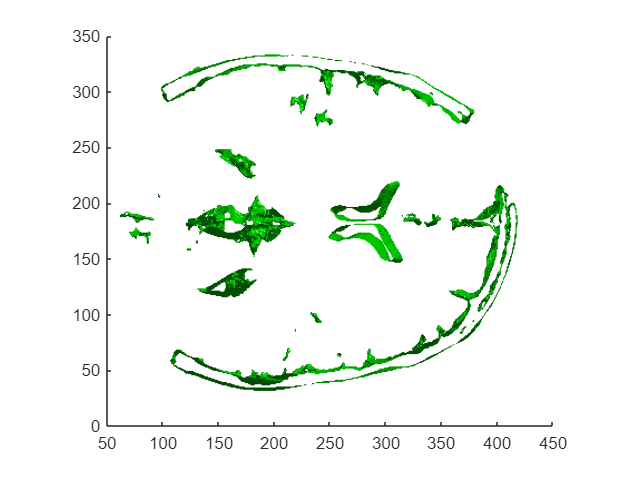

% Display CSF 3D Segment
figure;
p_3 = patch(isosurface(double(bw_13)));
p_3.FaceColor = 'green';
p_3.EdgeColor = 'none';
daspect([1 1 27/128]);
camlight; 
lighting phong

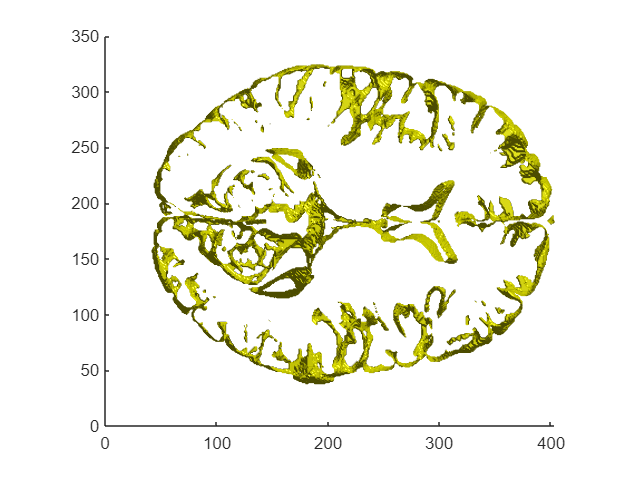

% Display Grey Matter 3D Segment
figure;
p_4 = patch(isosurface(double(bw_14)));
p_4.FaceColor = 'yellow';
p_4.EdgeColor = 'none';
daspect([1 1 27/128]);
camlight; 
lighting phong

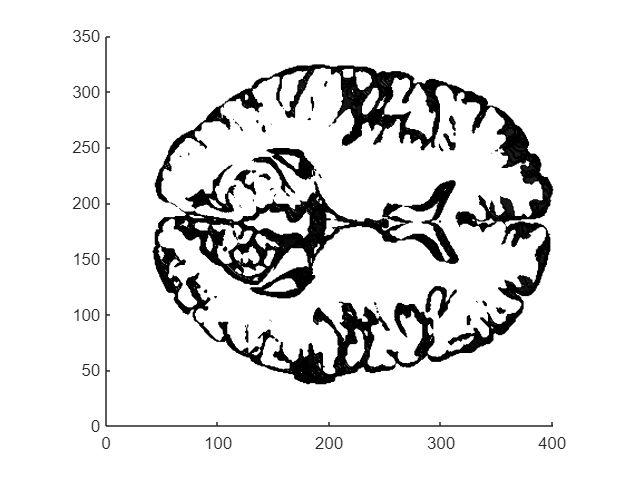

% Display White Matter 3D Segment
figure;
p_5 = patch(isosurface(double(bw_15)));
p_5.FaceColor = 'black';
p_5.EdgeColor = 'none';
daspect([1 1 27/128]);
camlight; 
lighting phong

% Adding final binaries
final_3d_image = bw_11+bw_12+bw_13+bw_14+bw_15;

% Calculating final 3D Dice score
final_3d_image_1 = cast(final_3d_image,'logical');
final_3d_groundTruth = cast(label, 'logical');
sim_dice_3d = dice(final_3d_image_1, final_3d_groundTruth);
sim_dice_3d

sim_dice_3d = 0.9400

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



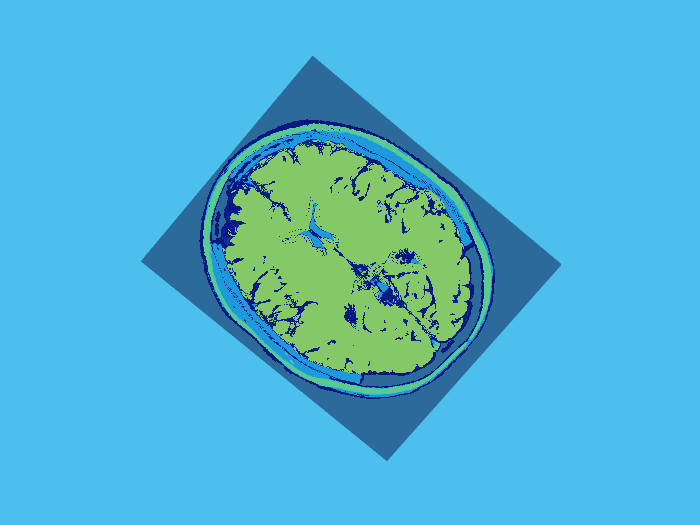

% 3D image display from Volume viewer
volshow(final_3d_image, config1);